s0_add_paths;

## Define some variables

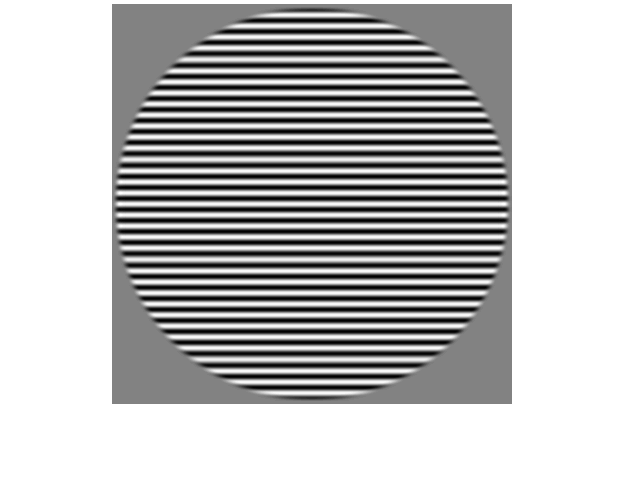

ds = 1; ep = 5; label = 10;
sigma_p = .8;
sigma_g = .8;
sigma_s = .01;
numpix  = 40; 
filter_cpd = [.75, 1.5, 3, 6];


% get stimuli 
fname = sprintf('stimuli-dataset%02d_orig.mat', ds); 
path  = fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli');
stimuli  = double(stimuli);
stimuli  = stimuli./255 - .5;
stim = stimuli(:, :, :, label); 
figure();
imshow(stim(:,:,ep,1), [])
title(sprintf('%d x %d', size(stim,1), size(stim,2)))


% get contrast energy
[Gabor_c, Gabor_s] = get_Filters(stimuli, ds, filter_cpd);
[E_ori, E_xy] = cal_E(stim, ds, Gabor_c, Gabor_s);

.


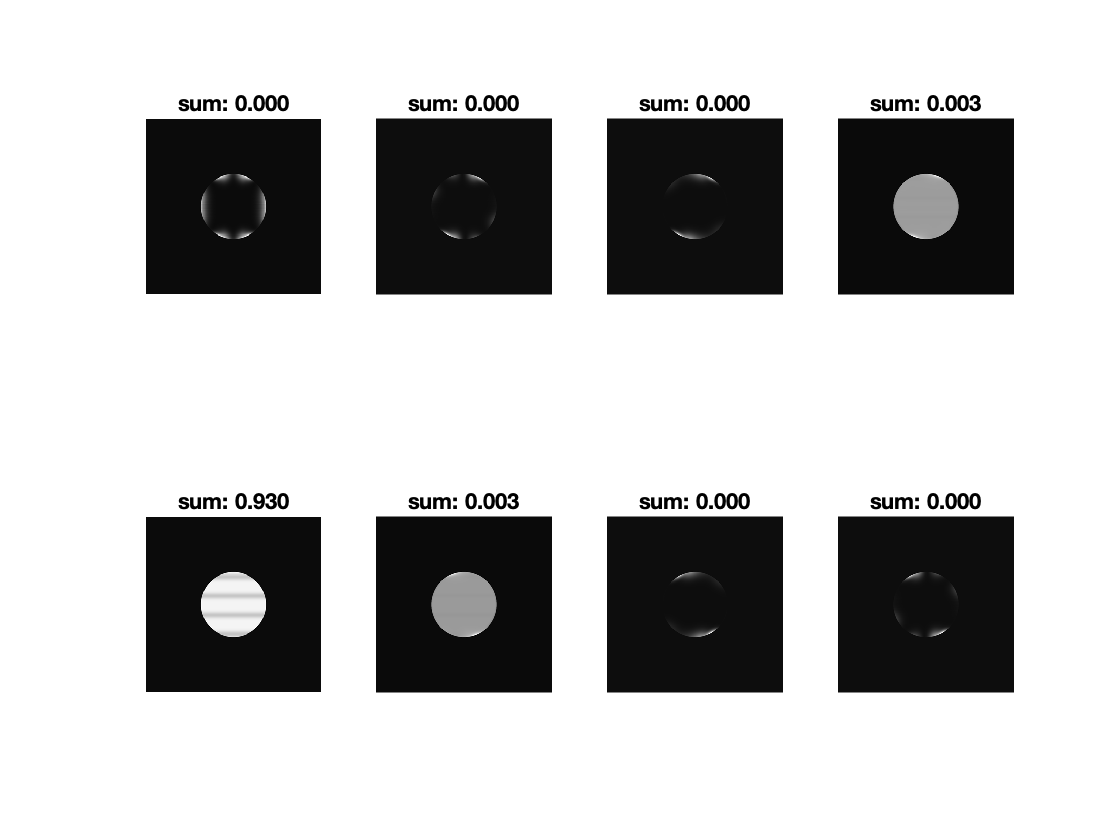

figure();
for i = 1:8
    subplot(2, 4, i)
    e = E_xy(:, :, i, ep, 1);
    imshow(e, [])
    title(sprintf('sum: %.3f', mean(e(:))))
    
end

## The OTS model using the new codes

mode    = 'oriTuned'; 
F = kernel_weight(sigma_p, sigma_g, sigma_s, numpix, mode);
size(F)

ans =     40    40     8     8


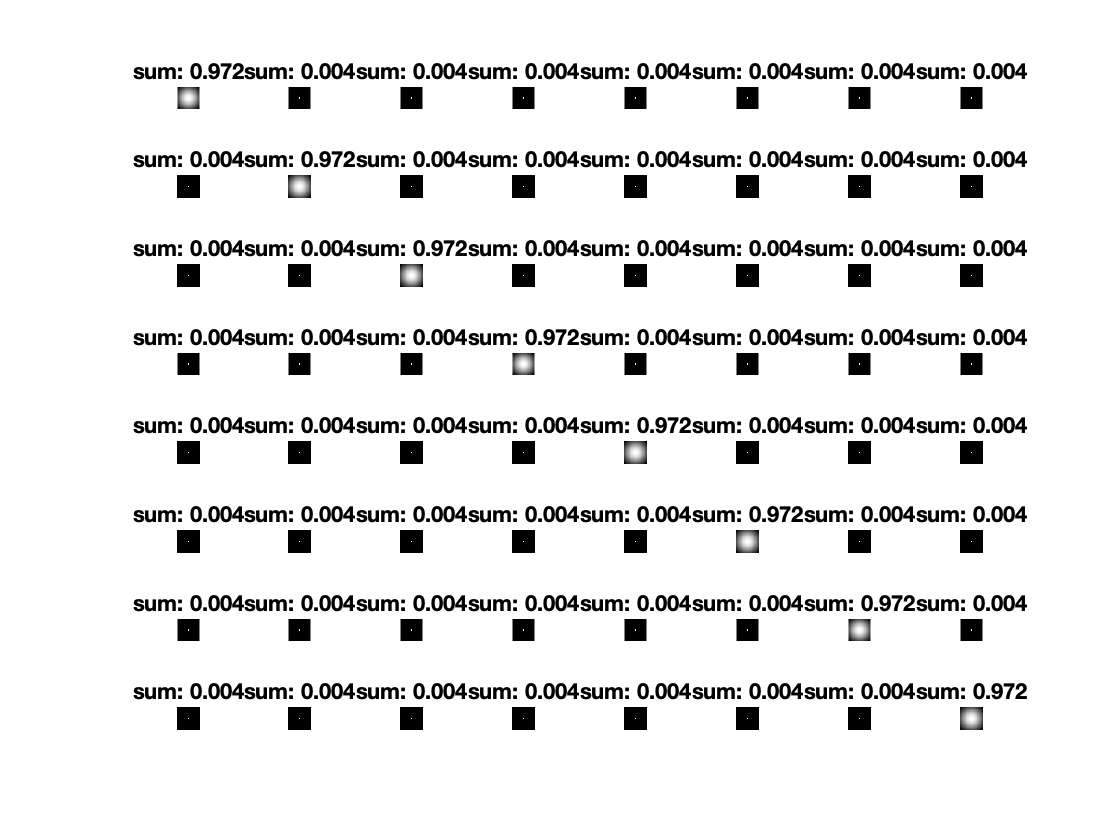

figure();
for i=1:8
    for j=1:8
        subplot(8, 8, (i-1)*8+j)
        f = F(:, :, i, j);
        imshow(f, [])
        title(sprintf('sum: %.3f', sum(f(:))))
    end
end

% Calculate Z 
Z1 = cal_Z(E_xy);

.


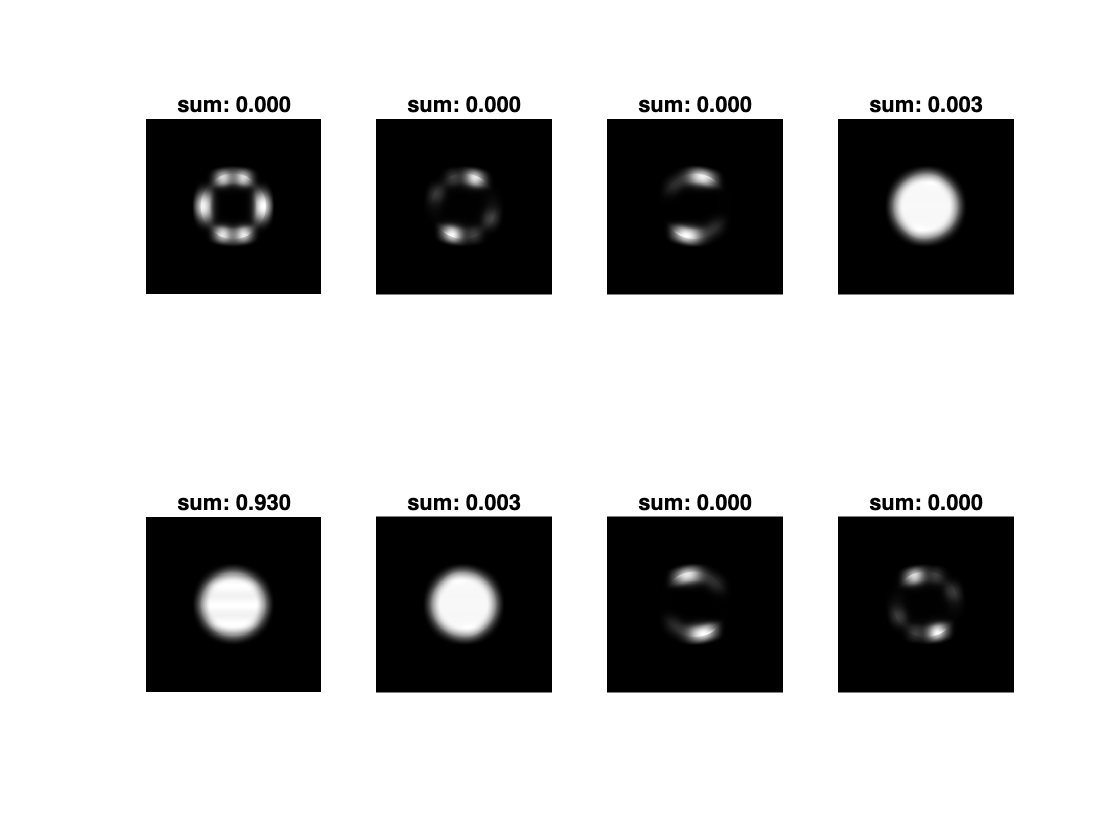

figure()
for i=1:8
    subplot(2, 4, i)
    z = Z1(:, :, i, ep, 1);
    imshow(z, [])
    title(sprintf('sum: %.3f', mean(z(:))))
end

## No orientation tuned

mode = 'notTuned';
% create the filters that are not orientational tuned 
sigma_s = sigma_p;
F = kernel_weight(sigma_p, sigma_g, sigma_s, numpix, mode);
size(F)

ans =     40    40     8     8


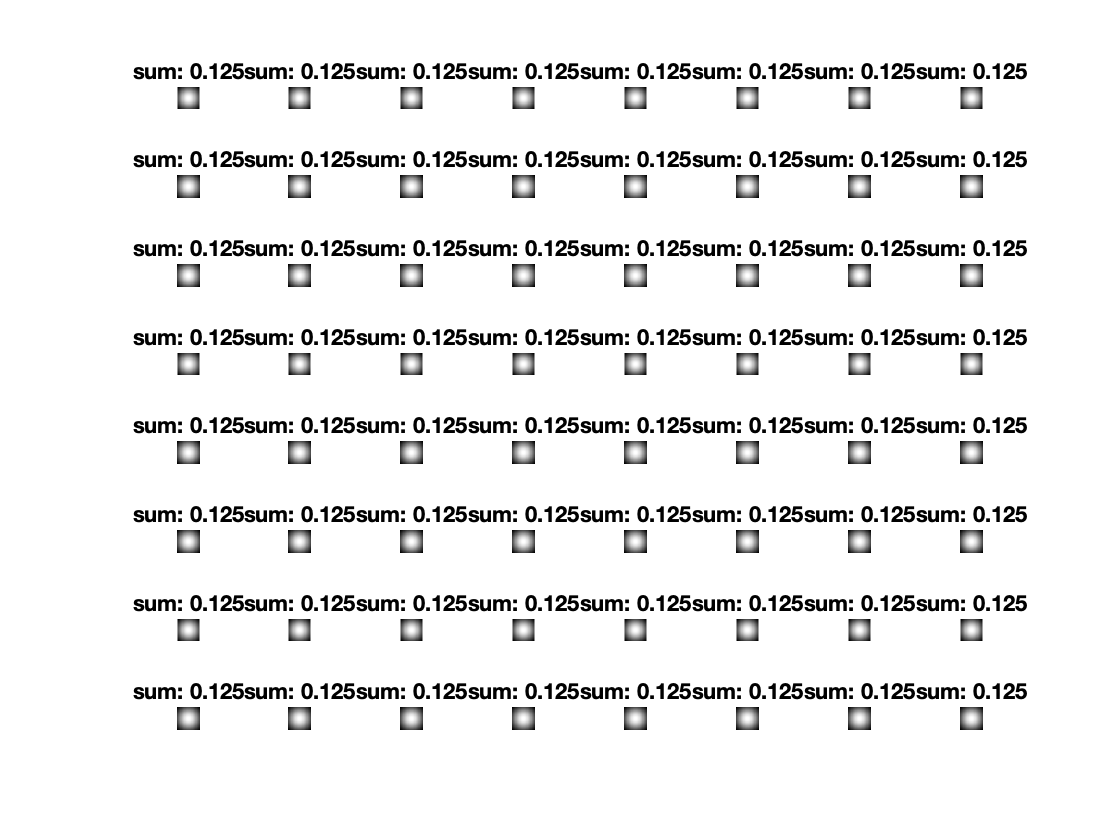

figure();
for i=1:8
    for j = 1:8
        subplot(8, 8, (i-1)*8+j)
        f = F(:, :, i, j);
        imshow(f, [])
        title(sprintf('sum: %.3f', sum(f(:))))
    end
end

figure();
Z2 = cal_Z(E_xy, mode);

.


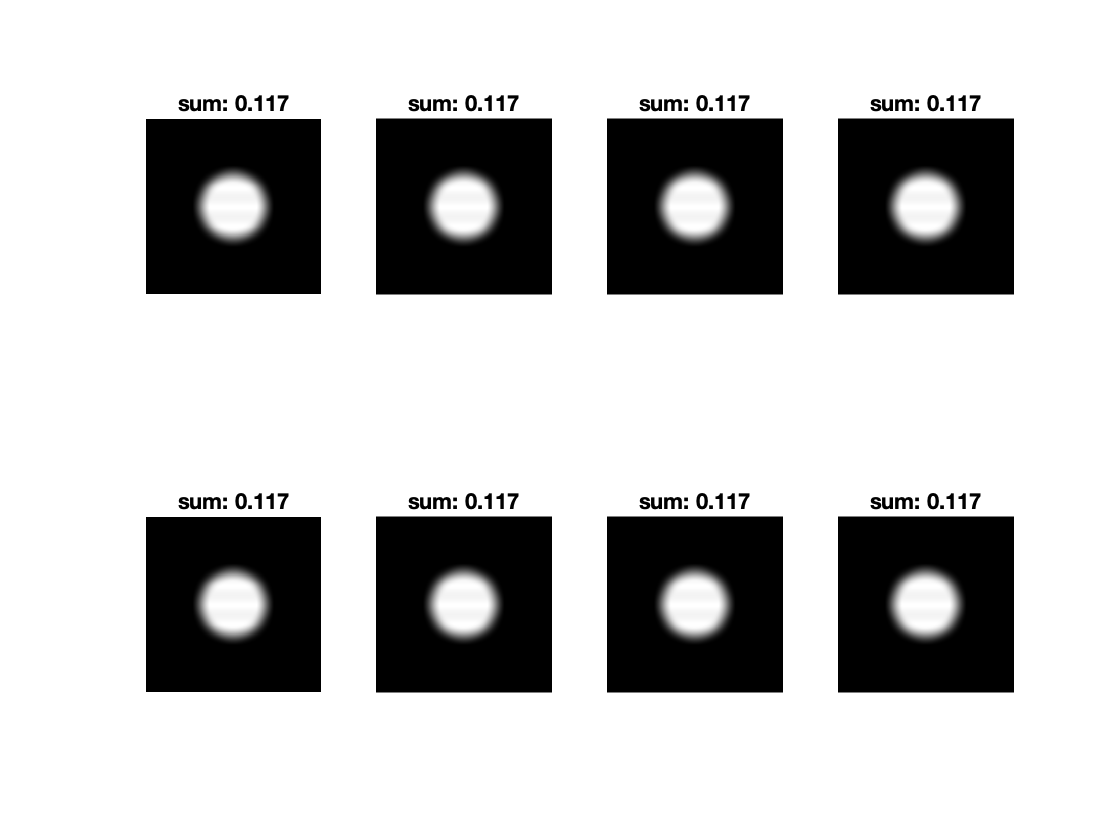

figure()
for i=1:8
    subplot(2, 4, i)
    z = Z2(:, :, i, ep, 1);
    imshow(z, [])
    title(sprintf('sum: %.3f', mean(z(:))))
end